HW15 Speckled noise and filtered

img = imread("images/rgb2.jpg");
img = img(:, :, 1);

t_spk = imnoise(img,"speckle");
"Speckled noise Vs. Median filtered speckled noise"

ans = "Speckled noise Vs. Median filtered speckled noise"

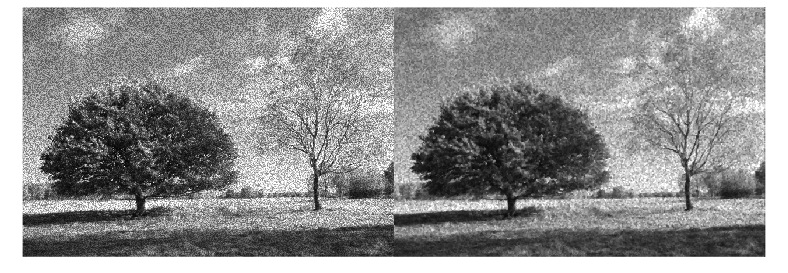

montage([t_spk, medfilt2(t_spk)])

HW16 Experiment with different D values for noise cleaning

d = [0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9, 1];
[x, y] = size(t_spk);
imgs = []


imgs =

     []



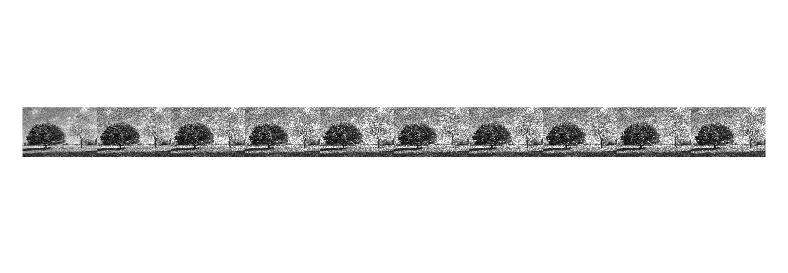

f = [0.125 0.125 0.125; 0.125 0 0.125; 0.125 0.125 0.125];
imd=im2double(t_spk);
imf=filter2(f,imd);
for i = 1:10
    r=abs(imd-imf)-d(i)>0;
    imgs = [imgs, im2uint8(r.*imf+(1-r).*imd)];
end
montage(imgs);

HW17 Apply average filtering

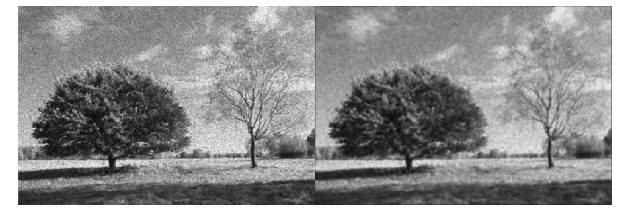

a3 = fspecial("average");
a5 = fspecial("average", [5,5]);
montage([filter2(a3, t_spk) / 255, filter2(a5, t_spk) / 255])